# 準ホップ代数$\widetilde{\mathbb C[\mathbb Z_n]}
$

#### 概要

太田さんのノート

『quasi Hopf algebra上のHeisenberg double および Drinfeld double の具体例』

を参考に，巡回群の群環上に準ホップ代数構造を定めて計算を行う．

さらにDrinfeld double of quasi Hopf algebraについても考察を行う．

#### 関連ファイル

`VectQuasiCyclic.m クラス`

## quasi Hopf alg strc.

#### Declare alg

[Z,g]=VectQuasiC2.getGenerator(1)

Z =     VectQuasiC2 object
    coeff    base
    _____    ____
      0       -  

g =     VectQuasiC2 object
    coeff    base
    _____    ____
      1       e1 

BaseConverter.H.add(g(1).bs,g(1).bs2,[1,1;1,-1])

#### Verify quasi-Hopf strc.

Z.verifyHopf(@(x,y)eqD(x,y,1e-10),["bialg"])

Confirmed to be a Hopf algebra


Z.getSC('counit')

ans = SparseEx [2] with 2 non-zero entries:
  (1)  1
  (2)  1

pp=1/2*(1+g)

pp =     VectQuasiC2 object
    coeff    base
    _____    ____
      1       p+ 

pm=1/2*(1-g)

pm =     VectQuasiC2 object
    coeff    base
    _____    ____
      1       p- 

pp^2-pp

ans =     VectQuasiC2 object
    coeff    base
    _____    ____
      0       -  

pp*pm

ans =     VectQuasiC2 object
    coeff    base
    _____    ____
      0       -  

Psi=(pp.unit|pp.unit|pp.unit)-2*(pm|pm|pm)

Psi =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
      1      p- ⊗ p+ ⊗ p+
      1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
      1      p+ ⊗ p+ ⊗ p-
      1      p- ⊗ p+ ⊗ p-
      1      p+ ⊗ p- ⊗ p-
     -1      p- ⊗ p- ⊗ p-

Psi^2-1

ans =     VectQuasiC2 object
    coeff    base
    _____    ____
      0       -  

Psi*(g|g|g)*Psi

ans =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
     -1      p- ⊗ p+ ⊗ p+
     -1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
     -1      p+ ⊗ p+ ⊗ p-
      1      p- ⊗ p+ ⊗ p-
      1      p+ ⊗ p- ⊗ p-
     -1      p- ⊗ p- ⊗ p-

g|g|g

ans =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
     -1      p- ⊗ p+ ⊗ p+
     -1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
     -1      p+ ⊗ p+ ⊗ p-
      1      p- ⊗ p+ ⊗ p-
      1      p+ ⊗ p- ⊗ p-
     -1      p- ⊗ p- ⊗ p-

Psi*(g|g|g.unit)*Psi

ans =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
     -1      p- ⊗ p+ ⊗ p+
     -1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
      1      p+ ⊗ p+ ⊗ p-
     -1      p- ⊗ p+ ⊗ p-
     -1      p+ ⊗ p- ⊗ p-
      1      p- ⊗ p- ⊗ p-

Psi*(g|g|1)*Psi

ans =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
     -1      p- ⊗ p+ ⊗ p+
     -1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
      1      p+ ⊗ p+ ⊗ p-
     -1      p- ⊗ p+ ⊗ p-
     -1      p+ ⊗ p- ⊗ p-
      1      p- ⊗ p- ⊗ p-

Psi=Z|Z|Z;
Psi.sparse=Z.getSC('associator')

Psi =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
      1      p- ⊗ p+ ⊗ p+
      1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
      1      p+ ⊗ p+ ⊗ p-
      1      p- ⊗ p+ ⊗ p-
      1      p+ ⊗ p- ⊗ p-
     -1      p- ⊗ p- ⊗ p-

[Z,p2]=VectQuasiC2.getGenerator(2)

Z =     VectQuasiC2 object
    coeff    base
    _____    ____
      0       -  

p2 =     VectQuasiC2 object
    coeff    base
    _____    ____
      1       p+ 
    VectQuasiC2 object
    coeff    base
    _____    ____
      1       p- 

Psi_=Z.getSC('associator');
Psi=Z|Z|Z;
Psi.sparse=Psi_;
ZB=VectHeisenbergDouble.getGenerator2(Z,'Hh2')

ZB =     VectHeisenbergDouble object
    coeff    base
    _____    ____
      0       -  

C=[1,1;1,-1];
ZB.make(1,2)

ans =     VectHeisenbergDouble object
    coeff       base    
    _____    ___________
      1      φ_{p-} # p+

% ZB.bs.setVar(4,["q+#p+","q-#p+","q+#p-","q-#p-"])
ZB.bs.setVar(4,["q_p#p_p","q_m#p_p","q_p#p_m","q_m#p_m"])

ans = Basis:[Hh2]
[q_p#p_p, q_m#p_p, q_p#p_m, q_m#p_m]

ZB.make(1,2)

ans =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_m#p_p

% BaseConverter.H.add(ZB.bs,Bases(4,["q+#p+","q-#p+","q+#p-","q-#p-"],"Hh2"),kron(C,C))


pp=ZB.make(1,1)

pp =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_p#p_p

mp=ZB.make(1,2)

mp =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_m#p_p

pm=ZB.make(1,3)

pm =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_p#p_m

mm=ZB.make(1,4)

mm =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_m#p_m

u=arrayfun(@(x)ZB.make(1,x),[1,3,2,4]);
prodT=strings(5,5); prodT(1)="";
for i=1:4
    prodT(1,i+1)=string(u(i));
    prodT(i+1,1)=string(u(i));
    for j=1:4
        prodT(i+1,j+1) = string(u(i)*u(j));
    end
end
pp*pp

ans =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_p#p_p

pp*mm

ans =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_m#p_m

mp*mm

ans =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
     -1      q_p#p_m

以下はnon-associativeな例

(mm*mp)*mm

ans =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_m#p_m

mm*(mp*mm)

ans =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
     -1      q_m#p_m

disp(categorical(prodT))

     <undefined>      (1)*q_p#p_p      (1)*q_p#p_m      (1)*q_m#p_p      (1)*q_m#p_m  
     (1)*q_p#p_p      (1)*q_p#p_p      0                0                (1)*q_m#p_m  
     (1)*q_p#p_m      0                (1)*q_p#p_m      (1)*q_m#p_p      0            
     (1)*q_m#p_p      (1)*q_m#p_p      0                0                (-1)*q_p#p_m 
     (1)*q_m#p_m      0                (1)*q_m#p_m      (1)*q_p#p_p      0            


disp(sym("q_p"))

$$q_{p}$$

str2sym("1  2")

$$ans = 12$$

I=ZB.unit

I =     VectHeisenbergDouble object
    coeff     base  
    _____    _______
      1      q_p#p_p
      1      q_p#p_m

% I.sparse
c_=@(x)ZB.make(1,x);
W=(c_(1)|c_(1))+(c_(1)|c_(3))+(c_(3)|c_(2))+(c_(3)|c_(4));
W13=(c_(1)|I|c_(1))+(c_(1)|I|c_(3))+(c_(3)|I|c_(2))+(c_(3)|I|c_(4))

W13 =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_p#p_p ⊗ q_m#p_p
      1      q_p#p_m ⊗ q_p#p_m ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_p#p_p ⊗ q_m#p_m
      1      q_p#p_m ⊗ q_p#p_m ⊗ q_m#p_m

Psi_=W13

Psi_ =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_p#p_p ⊗ q_m#p_p
      1      q_p#p_m ⊗ q_p#p_m ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_p#p_p ⊗ q_m#p_m
      1      q_p#p_m ⊗ q_p#p_m ⊗ q_m#p_m

sp=Psi.sparse;
sp.key=sp.key*2-1;
sp.size=[4,4,4];
Psi_.sparse=sp

Psi_ =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
     0.75    q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
     0.25    q_p#p_m ⊗ q_p#p_p ⊗ q_p#p_p
     0.25    q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_p
    -0.25    q_p#p_m ⊗ q_p#p_m ⊗ q_p#p_p
     0.25    q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
    -0.25    q_p#p_m ⊗ q_p#p_p ⊗ q_p#p_m
    -0.25    q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_m
     0.25    q_p#p_m ⊗ q_p#p_m ⊗ q_p#p_m

Psi_

Psi_ =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
     0.75    q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
     0.25    q_p#p_m ⊗ q_p#p_p ⊗ q_p#p_p
     0.25    q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_p
    -0.25    q_p#p_m ⊗ q_p#p_m ⊗ q_p#p_p
     0.25    q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
    -0.25    q_p#p_m ⊗ q_p#p_p ⊗ q_p#p_m
    -0.25    q_p#p_p ⊗ q_p#p_m ⊗ q_p#p_m
     0.25    q_p#p_m ⊗ q_p#p_m ⊗ q_p#p_m

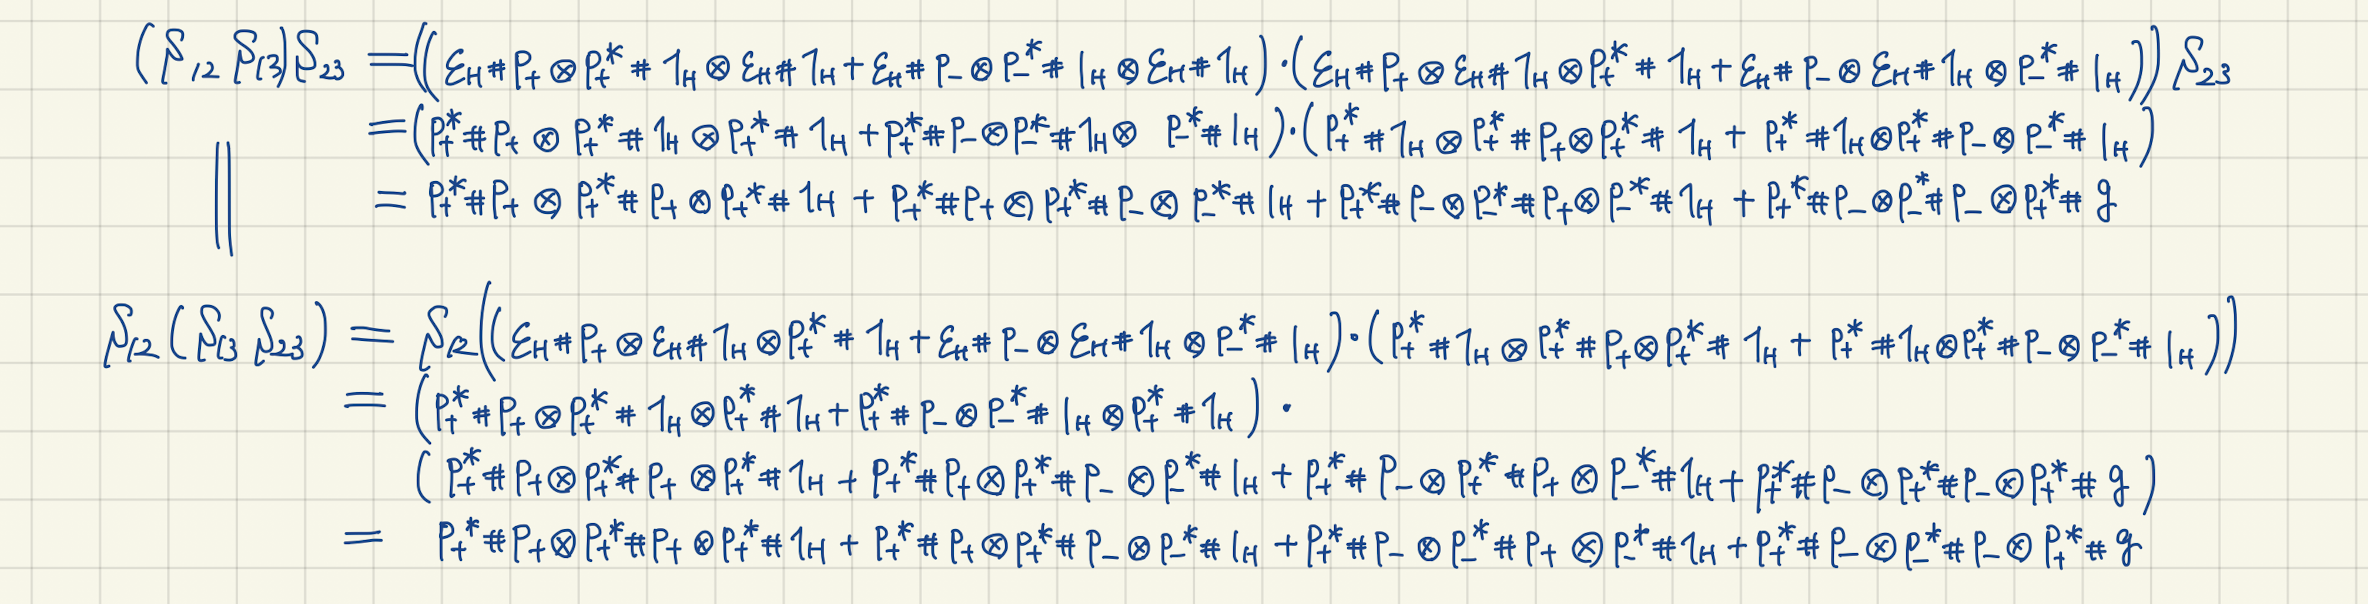

W12_3=(W|I)*W13*(I|W)

W12_3 =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_m#p_m ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_m#p_p ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
     -1      q_p#p_m ⊗ q_m#p_m ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_m#p_p ⊗ q_m#p_m
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_m#p_m

W1_23=(W|I)*W13*(I|W);
W1_23-W12_3

ans =     VectHeisenbergDouble object
    coeff    base
    _____    ____
      0       -  

(pp|pp|1)+(((pp|pm)+(pm|mp))|(mp+mm))+(pm|mm|(pp-pm))-W12_3

ans =     VectHeisenbergDouble object
    coeff    base
    _____    ____
      0       -  

% sp=ZB.sparse
% calcTensorExpression('sp{1}sp{2}',[1,2])
% 
% A.sparse
w123

w123 = SparseEx [4,4,4] with 8 non-zero entries:
  (1,1,1)  1
  (1,1,3)  1
  (1,3,2)  1
  (1,3,4)  1
  (3,2,2)  1
  (3,2,4)  1
  (3,4,1)  1
  (3,4,3)  -1

Psi

Psi =     VectQuasiC2 object
    coeff        base    
    _____    ____________
      1      p+ ⊗ p+ ⊗ p+
      1      p- ⊗ p+ ⊗ p+
      1      p+ ⊗ p- ⊗ p+
      1      p- ⊗ p- ⊗ p+
      1      p+ ⊗ p+ ⊗ p-
      1      p- ⊗ p+ ⊗ p-
      1      p+ ⊗ p- ⊗ p-
     -1      p- ⊗ p- ⊗ p-


function ret=act_r3(arg1,arg2)
    P1=arg2.getSC('prod');
    assert(arg1.rank==3&&arg2.rank==3)
    % P=P1;
    % for i=2:3
    %     P=P|P1;
    % end
    sp1=reshape(arg1.sparse,ones(1,6)*arg1.rdim);
    sp2=arg2.sparse;
    sp0=calcTensorExpression('sp1{10,1,11,4,12,7}P1{1,2,3}P1{4,5,6}P1{7,8,9}sp2{2,5,8}',[10,3,11,6,12,9]);
    ret=arg1;
    ret.sparse=reshape(sp0,arg1.dims);


end

LHS_pentagon=act_r3(W12_3,Psi)

LHS_pentagon =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_m#p_m ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_m#p_p ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_m#p_m ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_m#p_p ⊗ q_m#p_m
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_m#p_m

LHS_pentagon-W2312

ans =     VectHeisenbergDouble object
    coeff    base
    _____    ____
      0       -  


W2312=(I|W)*(W|I)

W2312 =     VectHeisenbergDouble object
    coeff               base            
    _____    ___________________________
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_m#p_m ⊗ q_p#p_p
      1      q_p#p_m ⊗ q_m#p_p ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_m#p_p
      1      q_p#p_p ⊗ q_p#p_p ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_m#p_m ⊗ q_p#p_m
      1      q_p#p_m ⊗ q_m#p_p ⊗ q_m#p_m
      1      q_p#p_p ⊗ q_p#p_m ⊗ q_m#p_m

(pp|pp|1)+(pm|mm|1)+(pp|pm|(mp+mm))+(pm|mp|(mp+mm))-W2312

ans =     VectHeisenbergDouble object
    coeff    base
    _____    ____
      0       -  

Psi.sparse

c_(1)


W13.sparse

